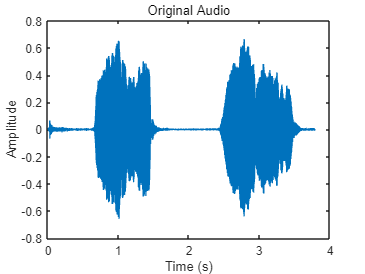

[audio_data, Fs] = audioread("2notes.wav");

len_time = length(audio_data) / Fs;


time = linspace(0, len_time, length(audio_data));


figure(1);
plot(time, audio_data);
title('Original Audio');
xlabel('Time (s)');
ylabel('Amplitude');

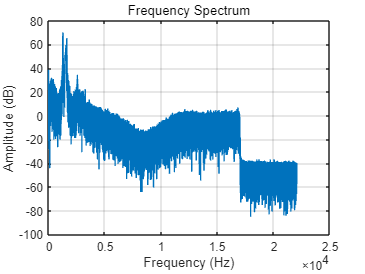


%frequency analysis
nfft = 2^nextpow2(length(audio_data)); % Selecting the number of FFT points
fft_result = fft(audio_data, nfft);
fft_result = fft_result(1:nfft/2); 
% Calculate the frequency axis
frequencies = (0:nfft/2-1) * Fs / nfft;


figure(2);
plot(frequencies, 20*log10(abs(fft_result))); 
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');


grid on;

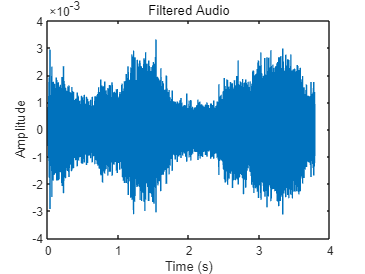


% Define parameters for the bandpass filter
center_freq = 13000;
lower_freq = 11000;
upper_freq = 15000;
filter_order = 100;

% Normalize frequencies
normalized_center_freq = center_freq / (Fs/2);
normalized_lower_freq = lower_freq / (Fs/2);
normalized_upper_freq = upper_freq / (Fs/2);

% Design a bandpass filter
bandpass_filter = fir1(filter_order, [normalized_lower_freq normalized_upper_freq], 'bandpass');

% Apply the bandpass filter to the audio data
filtered_audio = filter(bandpass_filter, 1, audio_data);


filtered_fft_result = fft(filtered_audio, nfft);
filtered_fft_result = filtered_fft_result(1:nfft/2);

figure(3);
plot(time, filtered_audio);
title('Filtered Audio');
xlabel('Time (s)');
ylabel('Amplitude');

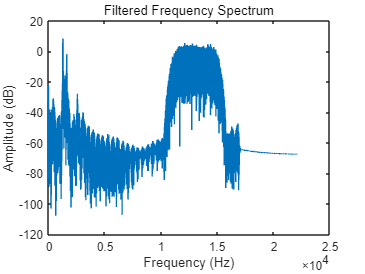


figure(4);
plot(frequencies, 20*log10(abs(filtered_fft_result)));
title('Filtered Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude (dB)');